
Cresults_ci_min = load('Cresults_ci_min.mat');
Cresults_ci_max = load('Cresults_ci_max.mat');
Cresults_D_max = load('Cresults_D_max.mat');

Cresults_D_min = load('Cresults_D_min.mat');
Cresults_D0 = load('Cresults_D0.mat');
Cresults_YZ_default = load('Cresults_YZ_default.mat');

modelData.solMin = min(Cresults_YZ_default.Cresults);

Cresults_YZ_default = struct with fields:
    Cresults: [118097×409 double]
      Xnodes: [118097×1 double]
      Ynodes: [118097×1 double]
    averageC: [409×1 double]
        minC: [409×1 double]
      solMax: [7970000 8.7941e+06 8.2152e+06 8.1118e+06 8.0482e+06 8.0087e+06 7.9871e+06 7.9663e+06 7.9523e+06 7.9344e+06 7.9087e+06 7.8760e+06 7.8373e+06 7.7933e+06 7.7452e+06 7.6939e+06 7.6431e+06 7.5903e+06 7.5361e+06 7.4807e+06 7.4246e+06 … ]


Cresults_YZ_default.solMax = max(Cresults_YZ_default.Cresults);
r = [2 , 2.5 , 3.5];  % Radius of tumour volume taken into account
Cresults_XZ_default = load('Cresults_XZ_default.mat');

's6_2_Cresults_average' is not found in the current folder or on the MATLAB path, but exists in:
    /Users/Eline/Documents/GitHub/MasterThesis/3D_ModellingDiffusion_CombinedBThTA_EK_2022

Change the MATLAB current folder or add its folder to the MATLAB path.

Cresults_XZ_default.Cresults = Cresults_ci_min.Cresults .*10^2;

Cresults_YZ_default.Cresults = Cresults_YZ_default.Cresults ./10^3

[modelData] = s6_2_Cresults_average(model,modelData,r(1),r(2),r(3),centretumor(1)); % C values (max,min,average) in GTV

[Cresults_YZ_default.averageC,Cresults_YZ_default.minC,results_order] = s6_2_Cresults_time(model,modelData,r(1),centretumor(1)); % averageT and minT only in tumour area

Cresults_YZ_default = struct with fields:
    Cresults: [118097×409 double]
      Xnodes: [118097×1 double]
      Ynodes: [118097×1 double]
    averageC: [409×1 double]
        minC: [409×1 double]
      solMax: [7.9700e+09 8.7941e+09 8.2152e+09 8.1118e+09 8.0482e+09 8.0087e+09 7.9871e+09 7.9663e+09 7.9523e+09 7.9344e+09 7.9087e+09 7.8760e+09 7.8373e+09 7.7933e+09 7.7452e+09 7.6939e+09 7.6431e+09 7.5903e+09 7.5361e+09 7.4807e+09 7.4246e+09 … ]


# Intersection graphs

## necrotic core diameter

Cresults_necrotic_1cm = load('Cresults_necrotic_1cm.mat');

averageC_GTV = 4.2007e+05

minC_GTV = 146.0072

maxC_GTV = 1.6597e+06

averageC_PTV = 388.4444

minC_PTV = 0.0115

maxC_PTV = 7.7719e+03

averageC_1cm = 0.0378

minC_1cm = 1.4755e-14

maxC_1cm = 1.4499

Cresults_XZ_default = load('Cresults_XZ_default.mat');
Cresults_necrotic_2cm = load('Cresults_necrotic_2cm.mat');
Cresults_necrotic_3cm = load('Cresults_necrotic_3cm.mat');
Cresults_necrotic_4cm = load('Cresults_necrotic_4cm.mat');


spread = Cresults_XZ_default.Cresults(:,409);
heatspread = [Cresults_XZ_default.Xnodes Cresults_XZ_default.Ynodes spread];
for i = 1:length(heatspread(:,2))
    if heatspread(i,2) >= 4.03 || heatspread(i,2) <= 3.97
        heatspread(i,2) = 0;
    end
end
heatspread(any(heatspread(:,2)==0,2),:) = [];
heatspread = sortrows(heatspread,1);

%%%%%% 1cm %%%%%
%Cresults_XZ_optimize = load('Cresults_XZ_optimize.mat')
spread1 = Cresults_necrotic_1cm.Cresults(:,409);
heatspread1_default = [Cresults_necrotic_1cm.Xnodes Cresults_necrotic_1cm.Ynodes spread1];
for i = 1:length(heatspread1_default(:,2))
    if heatspread1_default(i,2) >= 4.03 || heatspread1_default(i,2) <= 3.97
        heatspread1_default(i,2) = 0;
    end
end
heatspread1_default(any(heatspread1_default(:,2)==0,2),:) = [];
heatspread1_default = sortrows(heatspread1_default,1);

%%%%%% 2cm %%%%%
%Cresults_XZ_optimize = load('Cresults_XZ_optimize.mat')
spread2 = Cresults_necrotic_2cm.Cresults(:,409);
heatspread2_default = [Cresults_necrotic_2cm.Xnodes Cresults_necrotic_2cm.Ynodes spread2];
for i = 1:length(heatspread2_default(:,2))
    if heatspread2_default(i,2) >= 4.03 || heatspread2_default(i,2) <= 3.97
        heatspread2_default(i,2) = 0;
    end
end
heatspread2_default(any(heatspread2_default(:,2)==0,2),:) = [];
heatspread2_default = sortrows(heatspread2_default,1);

%%%%%% 3cm %%%%%
spread3 = Cresults_necrotic_3cm.Cresults(:,409);
heatspread3 = [Cresults_necrotic_3cm.Xnodes Cresults_necrotic_3cm.Ynodes spread3];
for i = 1:length(heatspread3(:,2))
    if heatspread3(i,2) >= 4.03 || heatspread3(i,2) <= 3.97
        heatspread3(i,2) = 0;
    end
end
heatspread3(any(heatspread3(:,2)==0,2),:) = [];
heatspread3 = sortrows(heatspread3,1);

%%%%%% 4cm %%%%%
spread4 = Cresults_necrotic_4cm.Cresults(:,409);
heatspread4 = [Cresults_necrotic_4cm.Xnodes Cresults_necrotic_4cm.Ynodes spread4];
for i = 1:length(heatspread4(:,2))
    if heatspread4(i,2) >= 4.03 || heatspread4(i,2) <= 3.97
        heatspread4(i,2) = 0;
    end
end
heatspread4(any(heatspread4(:,2)==0,2),:) = [];
heatspread4 = sortrows(heatspread4,1);


figure
plot(heatspread(:,1),heatspread(:,3),'-','Linewidth',2)
hold on 
plot(heatspread1_default(:,1),heatspread1_default(:,3),'-','Linewidth',2)
plot(heatspread2_default(:,1),heatspread2_default(:,3),'-','Linewidth',2)
plot(heatspread3(:,1),heatspread3(:,3),'-','Linewidth',2)
plot(heatspread4(:,1),heatspread4(:,3),'-','Linewidth',2)
xline(2);
xline(6);
xline(1.5);
xline(6.5);
%yline(48,[2 6])
set(gca,'FontSize',16)
title("Spread of heat at t = 20 min for different necrotic diameters",'FontSize',18)
txt = {'intersection through centre of tumour'};
subtitle(txt,'FontSize',25)
ylabel(['Temperature (' char(176) 'C)'],'FontSize',22)
xlabel("Distance (cm)",'FontSize',22)
legend("d = 0 cm","d = 1 cm","d = 2 cm","d = 3 cm","d = 4 cm")
%clb = colorbar;
%set(get(clb,'label'),'string',['Temperature (' char(176) 'C)'],'FontSize',22);

%ylim([37 38])

## wb min max

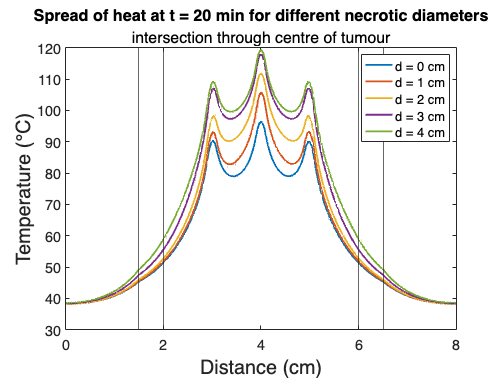

Cresults_wb_min = load('Cresults_wb_min.mat');
Cresults_XZ_default = load('Cresults_XZ_default.mat');
Cresults_wb_max = load('Cresults_wb_max.mat');


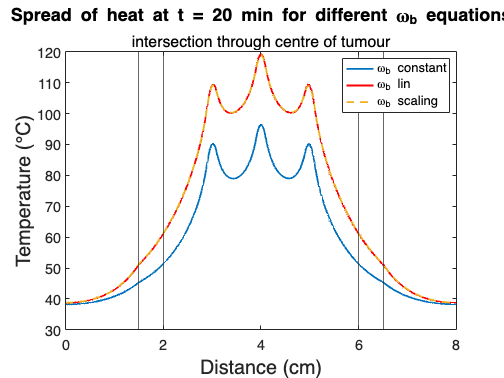


spread = Cresults_XZ_default.Cresults(:,409);
heatspread = [Cresults_XZ_default.Xnodes Cresults_XZ_default.Ynodes spread];
for i = 1:length(heatspread(:,2))

    if heatspread(i,2) >= 4.03 || heatspread(i,2) <= 3.97
        heatspread(i,2) = 0;
    end
end
heatspread(any(heatspread(:,2)==0,2),:) = [];
heatspread = sortrows(heatspread,1);

%%%%%% min %%%%%
%Cresults_XZ_optimize = load('Cresults_XZ_optimize.mat')
spread2 = Cresults_wb_min.Cresults(:,409);
heatspread2_default = [Cresults_wb_min.Xnodes Cresults_wb_min.Ynodes spread2];
for i = 1:length(heatspread2_default(:,2))
    if heatspread2_default(i,2) >= 4.03 || heatspread2_default(i,2) <= 3.97
        heatspread2_default(i,2) = 0;
    end
end
heatspread2_default(any(heatspread2_default(:,2)==0,2),:) = [];
heatspread2_default = sortrows(heatspread2_default,1);

%%%%%% max %%%%%
spread3 = Cresults_wb_max.Cresults(:,409);
heatspread3 = [Cresults_wb_max.Xnodes Cresults_wb_max.Ynodes spread3];
for i = 1:length(heatspread3(:,2))
    if heatspread3(i,2) >= 4.03 || heatspread3(i,2) <= 3.97
        heatspread3(i,2) = 0;
    end
end
heatspread3(any(heatspread3(:,2)==0,2),:) = [];
heatspread3 = sortrows(heatspread3,1);

figure
plot(heatspread2_default(:,1),heatspread2_default(:,3),'-','Linewidth',2)
hold on
plot(heatspread(:,1),heatspread(:,3),'-','Linewidth',2)
plot(heatspread3(:,1),heatspread3(:,3),'-','Linewidth',2)
xline(2);
xline(6);
xline(1.5);
xline(6.5);
%yline(48,[2 6])
set(gca,'FontSize',16)
title("Spread of heat at t = 20 min for different \omega_b",'FontSize',22)
txt = {'intersection through centre of tumour'};
subtitle(txt,'FontSize',25)
ylabel(['Temperature (' char(176) 'C)'],'FontSize',22)
xlabel("Distance (cm)",'FontSize',22)
legend("\omega_b min","\omega_b","\omega_b max")
%clb = colorbar;
%set(get(clb,'label'),'string',['Temperature (' char(176) 'C)'],'FontSize',22);

%ylim([37 38])




## ci min max

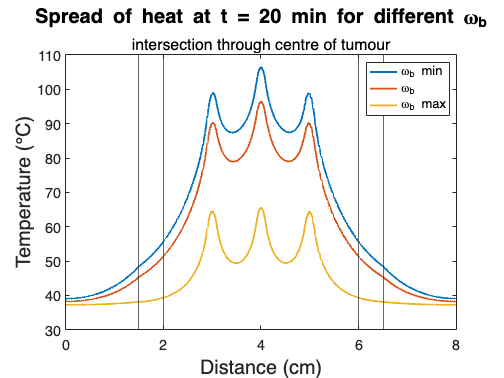


spread = Cresults_XZ_default.Cresults(:,409);
heatspread = [Cresults_XZ_default.Xnodes Cresults_XZ_default.Ynodes spread];

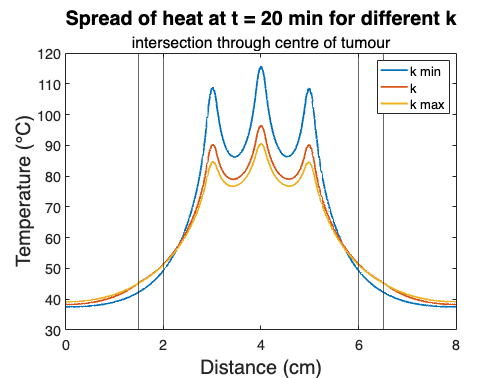

for i = 1:length(heatspread(:,2))
    if heatspread(i,2) >= 4.03 || heatspread(i,2) <= 3.97
        heatspread(i,2) = 0;
    end
end
heatspread(any(heatspread(:,2)==0,2),:) = [];
heatspread = sortrows(heatspread,1);


%%%%%% min %%%%%
%Cresults_XZ_optimize = load('Cresults_XZ_optimize.mat')
spread2 = Cresults_ci_min.Cresults(:,409);
heatspread2_default = [Cresults_ci_min.Xnodes Cresults_ci_min.Ynodes spread2];
for i = 1:length(heatspread2_default(:,2))
    if heatspread2_default(i,2) >= 4.03 || heatspread2_default(i,2) <= 3.97
        heatspread2_default(i,2) = 0;
    end
end
heatspread2_default(any(heatspread2_default(:,2)==0,2),:) = [];
heatspread2_default = sortrows(heatspread2_default,1);

%%%%%% max %%%%%
spread3 = Cresults_ci_max.Cresults(:,409);
heatspread3 = [Cresults_ci_max.Xnodes Cresults_ci_max.Ynodes spread3];
for i = 1:length(heatspread3(:,2))
    if heatspread3(i,2) >= 4.03 || heatspread3(i,2) <= 3.97
        heatspread3(i,2) = 0;
    end
end
heatspread3(any(heatspread3(:,2)==0,2),:) = [];
heatspread3 = sortrows(heatspread3,1);

figure
plot(heatspread2_default(:,1),heatspread2_default(:,3),'-','Linewidth',2)
hold on
plot(heatspread(:,1),heatspread(:,3),'-','Linewidth',2)
plot(heatspread3(:,1),heatspread3(:,3),'-','Linewidth',2)
xline(2);
xline(6);
xline(1.5);
xline(6.5);
%yline(48,[2 6])
set(gca,'FontSize',16)
title("Spread of NP concentration at t = 17 days",'FontSize',22)
txt = {'intersection through centre of tumour'};
subtitle(txt,'FontSize',25)
ylabel('NP concentration (#NP/cm^2)','FontSize',22)
xlabel("Distance (cm)",'FontSize',22)
legend("c_i min","c_i","c_i max")
%clb = colorbar;
%set(get(clb,'label'),'string',['Temperature (' char(176) 'C)'],'FontSize',22);
set(gca,'YScale','log')
ylim([10^(-6) 10^12])



## XZ YZ

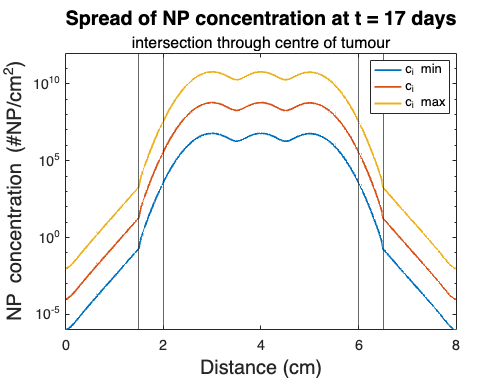


spread = Cresults_XZ_default.Cresults(:,409);
heatspread = [Cresults_XZ_default.Xnodes Cresults_XZ_default.Ynodes spread];
for i = 1:length(heatspread(:,2))
    if heatspread(i,2) >= 4.03 || heatspread(i,2) <= 3.97
        heatspread(i,2) = 0;
    end
end
heatspread(any(heatspread(:,2)==0,2),:) = [];
heatspread = sortrows(heatspread,1);


%%%%%% min %%%%%
%Cresults_XZ_optimize = load('Cresults_XZ_optimize.mat')
spread2 = Cresults_YZ_default.Cresults(:,409);
heatspread2_default = [Cresults_YZ_default.Xnodes Cresults_YZ_default.Ynodes spread2];
for i = 1:length(heatspread2_default(:,2))
    if heatspread2_default(i,2) >= 4.03 || heatspread2_default(i,2) <= 3.97
        heatspread2_default(i,2) = 0;
    end
end
heatspread2_default(any(heatspread2_default(:,2)==0,2),:) = [];
heatspread2_default = sortrows(heatspread2_default,1);


figure
plot(heatspread2_default(:,1),heatspread2_default(:,3),'-','Linewidth',2)
hold on
plot(heatspread(:,1),heatspread(:,3),'-','Linewidth',2)
%plot(heatspread3(:,1),heatspread3(:,3),'-','Linewidth',2)
xline(2);
xline(6);
xline(1.5);
xline(6.5);
%yline(48,[2 6])
set(gca,'FontSize',16)
title("Spread of NP concentration at t = 17 days",'FontSize',22)
txt = {'intersection through centre of tumour'};
subtitle(txt,'FontSize',25)
ylabel('NP concentration (#NP/cm^2)','FontSize',22)
xlabel("Distance (cm)",'FontSize',22)
legend("XZ","YZ")
%clb = colorbar;
%set(get(clb,'label'),'string',['Temperature (' char(176) 'C)'],'FontSize',22);
set(gca,'YScale','log')
%ylim([10^(-6) 10^12])



# Temperatures over time

## t min max

Cresults_t_min = load('Cresults_t_min.mat');
Cresults_wb_constant = load('Cresults_wb_constant.mat');
Cresults_t_max = load('Cresults_t_max.mat');

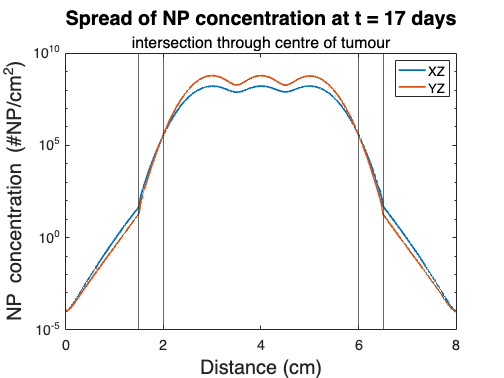


runData.timePoints = 0:0.1:90;
runData.timePointsX = 0:0.1:60;
figure
plot(runData.timePointsX,Cresults_t_min.solMax,'LineWidth',3)
hold on
plot(runData.timePoints,Cresults_wb_constant.solMax,'LineWidth',3)
plot(runData.timePointsX,Cresults_t_max.solMax,'LineWidth',3)
set(gca,'FontSize',16)
title('Maximum temperature in GTV over time','FontSize',25)

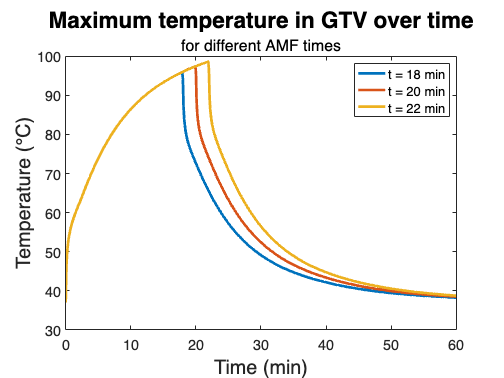

txt = {'for different AMF times'};
subtitle(txt,'FontSize',25)
ylabel(['Temperature (' char(176) 'C)'],'FontSize',22)
xlabel("Time (min)",'FontSize',22) 
legend("t = 18 min","t = 20 min","t = 22 min")
xlim([0 60])
%clb = colorbar;
%set(get(clb,'label'),'string',['Temperature (' char(176) 'C)'],'FontSize',22);

figure
plot(runData.timePointsX,Cresults_t_min.averageT,'LineWidth',3)
hold on
plot(runData.timePoints,Cresults_wb_constant.averageT,'LineWidth',3)
plot(runData.timePointsX,Cresults_t_max.averageT,'LineWidth',3)
set(gca,'FontSize',16)
title('Average temperature in GTV over time','FontSize',25)
txt = {'for different AMF times'};
subtitle(txt,'FontSize',25)
ylabel(['Temperature (' char(176) 'C)'],'FontSize',22)
xlabel("Time (min)",'FontSize',22) 
legend("t = 18 min","t = 20 min","t = 22 min")
xlim([0 60])

figure
plot(runData.timePointsX,Cresults_t_min.minT,'LineWidth',3)
hold on

plot(runData.timePoints,Cresults_wb_constant.minT,'LineWidth',3)
plot(runData.timePointsX,Cresults_t_max.minT,'LineWidth',3)
set(gca,'FontSize',16)
title('Minimum temperature in GTV over time','FontSize',25)
txt = {'for different AMF times'};
subtitle(txt,'FontSize',25)
ylabel(['Temperature (' char(176) 'C)'],'FontSize',22)
xlabel("Time (min)",'FontSize',22) 
legend("t = 18 min","t = 20 min","t = 22 min")
xlim([0 60])
%clb = colorbar;
%set(get(clb,'label'),'string',['Temperature (' char(176) 'C)'],'FontSize',22);

## ci min max

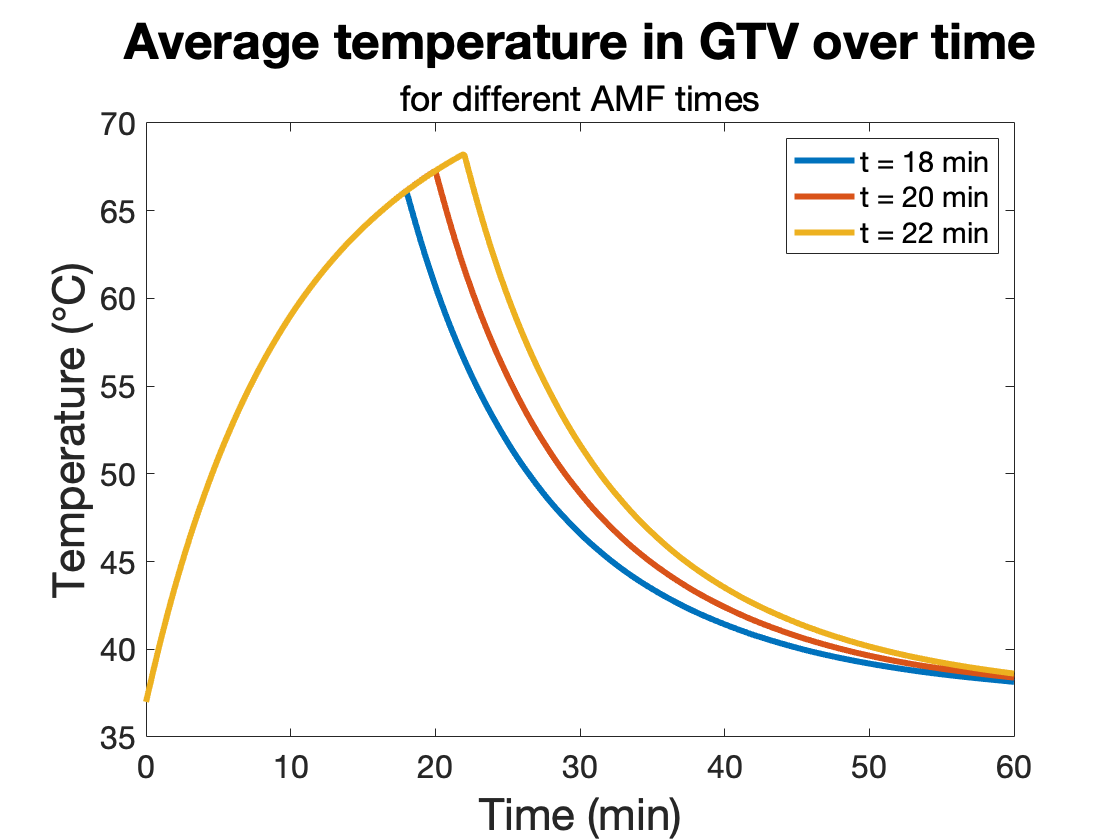

Cresults_YZ_default = load('Cresults_YZ_default.mat');
Cresults_wb_constant = load('Cresults_wb_constant.mat');
Cresults_ci_max = load('Cresults_ci_max.mat');


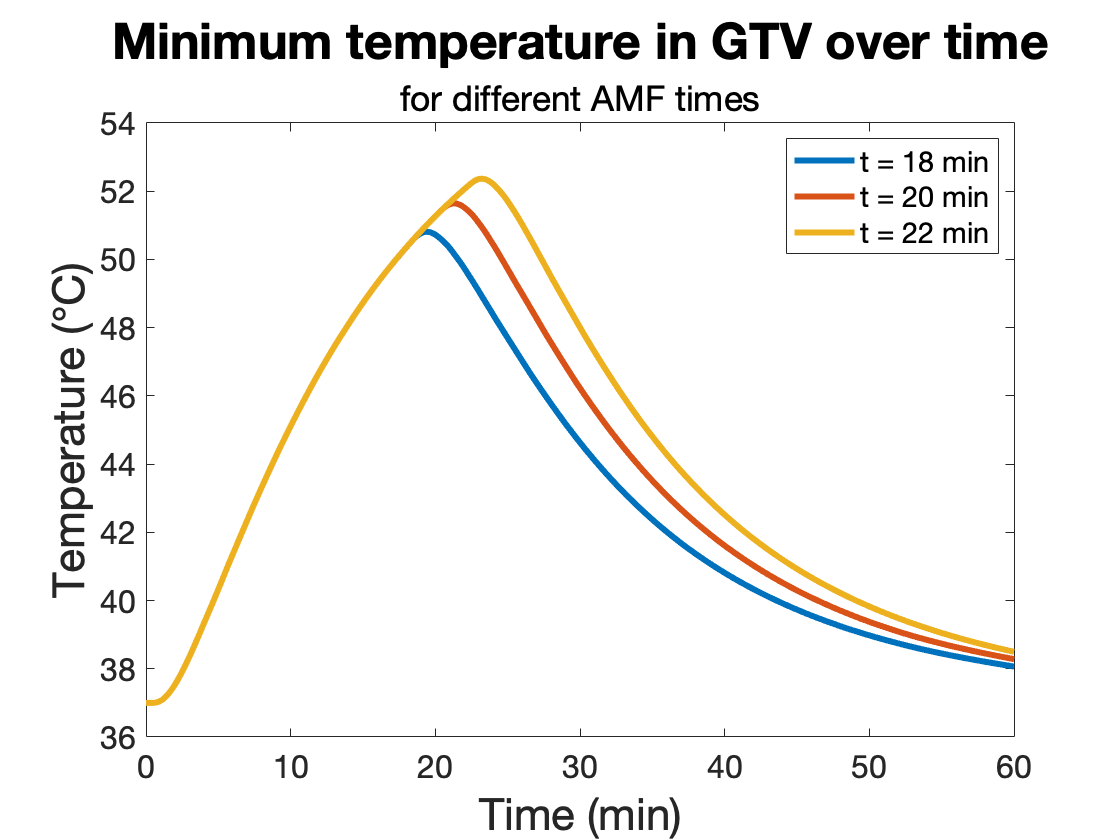

runData.timePointsX = 0:0.1:90;
figure
plot(runData.timePointsX,Cresults_YZ_default.solMax,'LineWidth',3)
hold on
plot(runData.timePointsX,Cresults_wb_constant.solMax,'LineWidth',3)
plot(runData.timePointsX,Cresults_ci_max.solMax,'LineWidth',3)
set(gca,'FontSize',16)
title('Maximum temperature in GTV over time','FontSize',25)
txt = {'for different heat sources Q_{NP}'};
subtitle(txt,'FontSize',25)
ylabel(['Temperature (' char(176) 'C)'],'FontSize',22)
xlabel("Time (min)",'FontSize',22) 
legend("Q_{NP} min","Q_{NP}","Q_{NP} max")
xlim([0 60])

%clb = colorbar;
%set(get(clb,'label'),'string',['Temperature (' char(176) 'C)'],'FontSize',22);

figure
plot(runData.timePointsX,Cresults_YZ_default.averageT,'LineWidth',3)

Error using load
Unable to find file or directory 'Cresults_ci_min.mat'.

hold on
plot(runData.timePointsX,Cresults_wb_constant.averageT,'LineWidth',3)
plot(runData.timePointsX,Cresults_ci_max.averageT,'LineWidth',3)
set(gca,'FontSize',16)
title('Average temperature in GTV over time','FontSize',25)
txt = {'for different heat sources Q_{NP}'};
subtitle(txt,'FontSize',25)
ylabel(['Temperature (' char(176) 'C)'],'FontSize',22)
xlabel("Time (min)",'FontSize',22) 
legend("Q_{NP} min","Q_{NP}","Q_{NP} max")
xlim([0 60])

figure
plot(runData.timePointsX,Cresults_YZ_default.minT,'LineWidth',3)
hold on
plot(runData.timePointsX,Cresults_wb_constant.minT,'LineWidth',3)
plot(runData.timePointsX,Cresults_ci_max.minT,'LineWidth',3)
set(gca,'FontSize',16)
title('Minimum temperature in GTV over time','FontSize',25)
txt = {'for different heat sources Q_{NP}'};
subtitle(txt,'FontSize',25)
ylabel(['Temperature (' char(176) 'C)'],'FontSize',22)
xlabel("Time (min)",'FontSize',22) 
legend("Q_{NP} min","Q_{NP}","Q_{NP} max")
xlim([0 60])
%clb = colorbar;
%set(get(clb,'label'),'string',['Temperature (' char(176) 'C)'],'FontSize',22);

## XZ YZ comparison

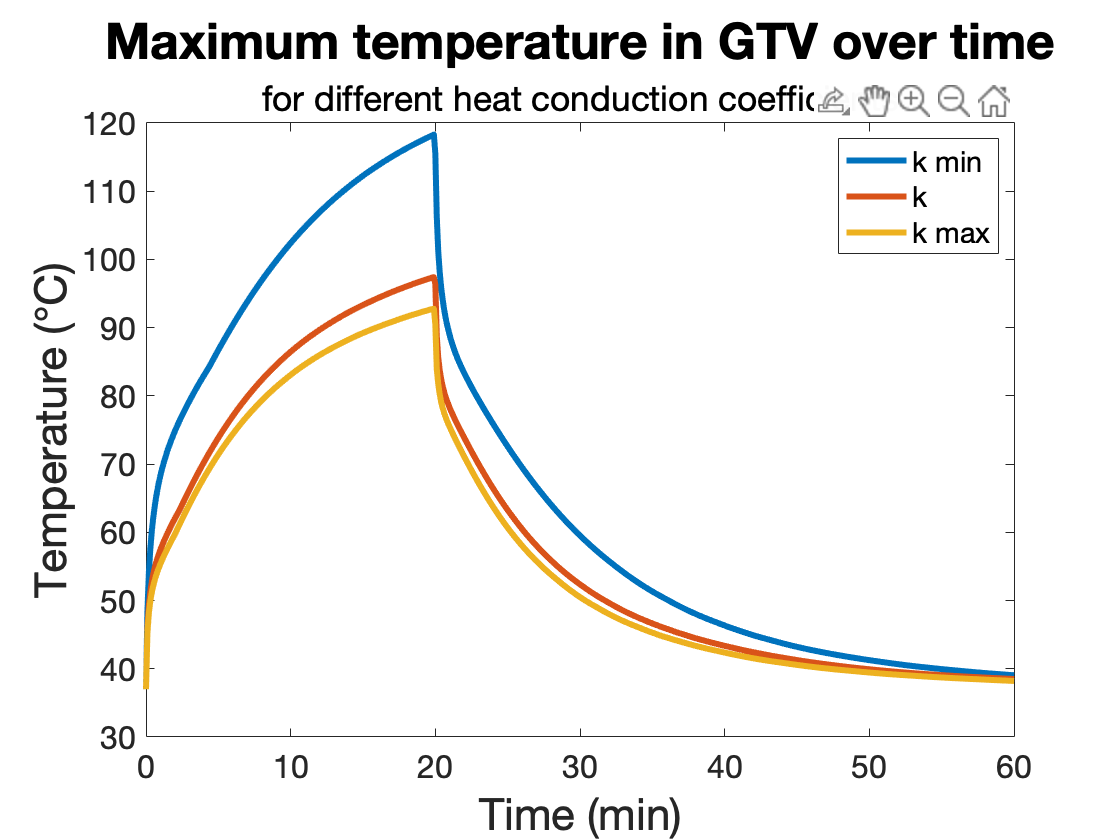

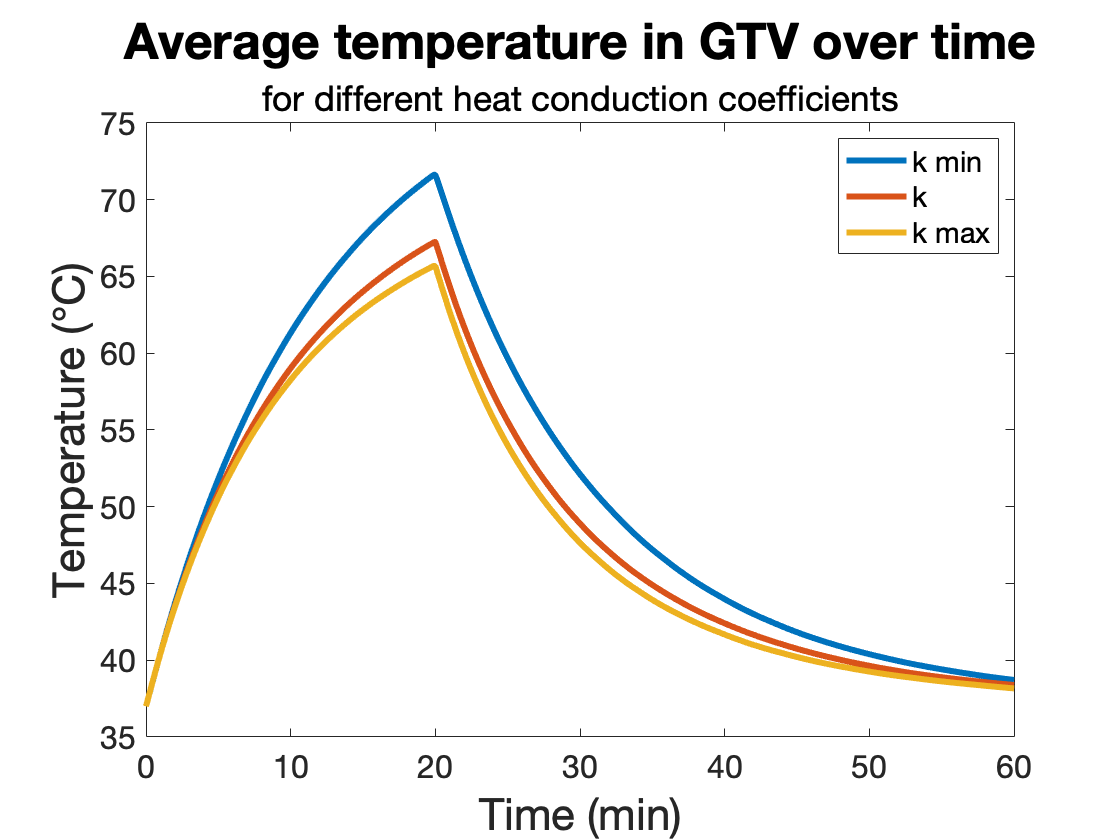

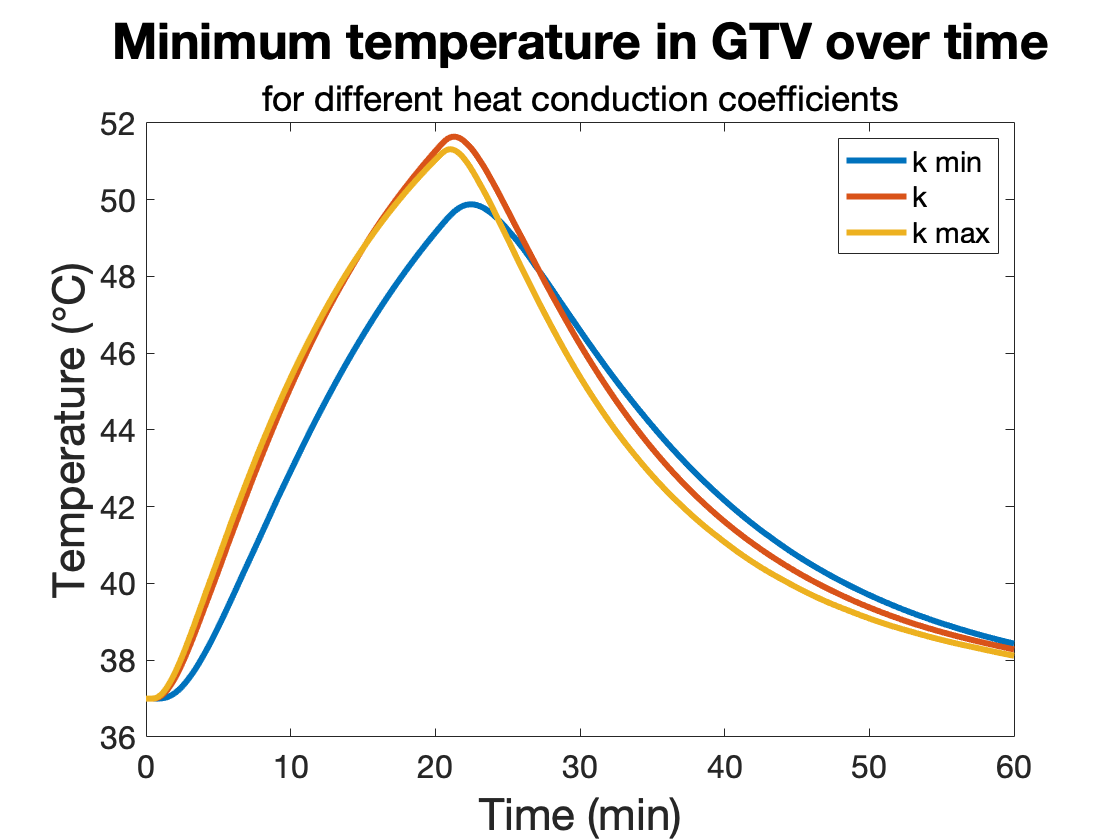

runData.timePoints = 0:1:24*17;
runData.timePoints = runData.timePoints/24

figure
plot(runData.timePoints,Cresults_XZ_default.solMax,'LineWidth',3,'Color',"#0000FF")
hold on
plot(runData.timePoints,Cresults_XZ_default.averageC,'LineWidth',3,'Color',"#0072BD")
plot(runData.timePoints,Cresults_XZ_default.minC,'LineWidth',3,'Color',"#4DBEEE")
plot(runData.timePoints,Cresults_YZ_default.solMax,'LineWidth',3,'Color',"#A2142F")
plot(runData.timePoints,Cresults_YZ_default.averageC,'LineWidth',3,'Color',"#D95319")
plot(runData.timePoints,Cresults_YZ_default.minC,'LineWidth',3,'Color',"#EDB120")
set(gca,'FontSize',16)
title('NP concentration in GTV over time','FontSize',25)
txt = {'for XZ and YZ plane'};
subtitle(txt,'FontSize',25)
ylabel('NP concentration (#NP/cm^2)','FontSize',22)
xlabel("Time (days)",'FontSize',22) 
legend("XZ C max","XZ C average","XZ C min","YZ C max","YZ C average","YZ C min")
%clb = colorbar;
%set(get(clb,'label'),'string',['Temperature (' char(176) 'C)'],'FontSize',22);
set(gca,'YScale','log')
ylim([10^(-10) 10^11])

xlim([0 17])

## Profiles XZ and YZ

figure
pdeplot(model,'XYData',Cresults_XZ_default.Cresults(:,409));
set(gca,'ColorScale','log')
caxis([10^(1) max(Cresults_XZ_default.solMax)])
hold on

runData = struct with fields:
         filename: 'testgif.gif'
          runType: 'time'
    checkGeometry: 1
     plotSolution: 1
             hmax: 0.0500
          dataset: 'Diff_driven'
       nEquations: 1
             nBCs: [1×1 struct]
              BCs: [1×1 struct]
             nICs: 2
               IC: [1×2 struct]
       timePoints: [0 0.0417 0.0833 0.1250 0.1667 0.2083 0.2500 0.2917 0.3333 0.3750 0.4167 0.4583 0.5000 0.5417 0.5833 0.6250 0.6667 0.7083 0.7500 0.7917 0.8333 0.8750 0.9167 0.9583 1 1.0417 1.0833 1.1250 1.1667 1.2083 1.2500 1.2917 1.3333 1.3750 … ]
         oneGroup: 1
      adjointFlag: 0
            group: 1
          nGroups: 1
          YZslice: "optimize1"


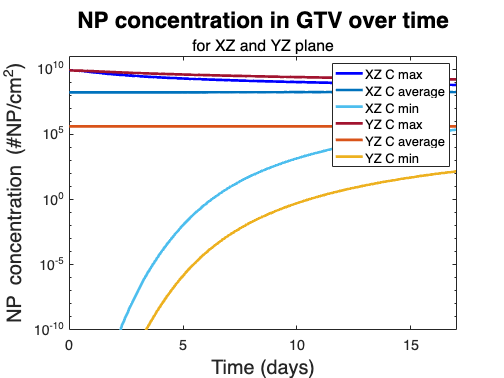

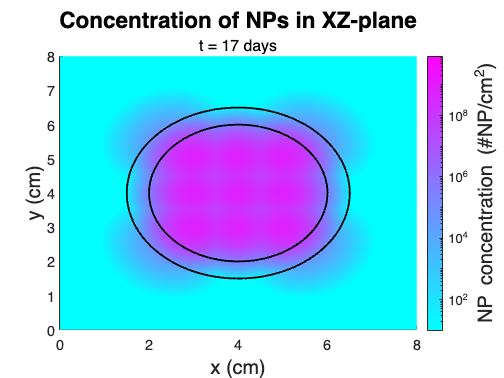

[xc, yc] = circle([4 4], 2.5,100); % radius determines radius of circles filling the area, n = number of coordinates calculated, less is less smooth circle (hoekig)    
plot(xc, yc, '-','linewidth',2,'Color','k');
[xc2, yc2] = circle([4 4], 2,100); % radius determines radius of circles filling the area, n = number of coordinates calculated, less is less smooth circle (hoekig)    
plot(xc2, yc2, '-','linewidth',2,'Color','k');
hold off
set(gca,'FontSize',16)
title('Concentration of NPs in XZ-plane','FontSize',25);
txt = {'t = 17 days'};
subtitle(txt,'FontSize',25)
ylabel('y (cm)','FontSize',22)
xlabel("x (cm)",'FontSize',22) 
clb = colorbar;
set(get(clb,'label'),'string','NP concentration (#NP/cm^2)','FontSize',22);